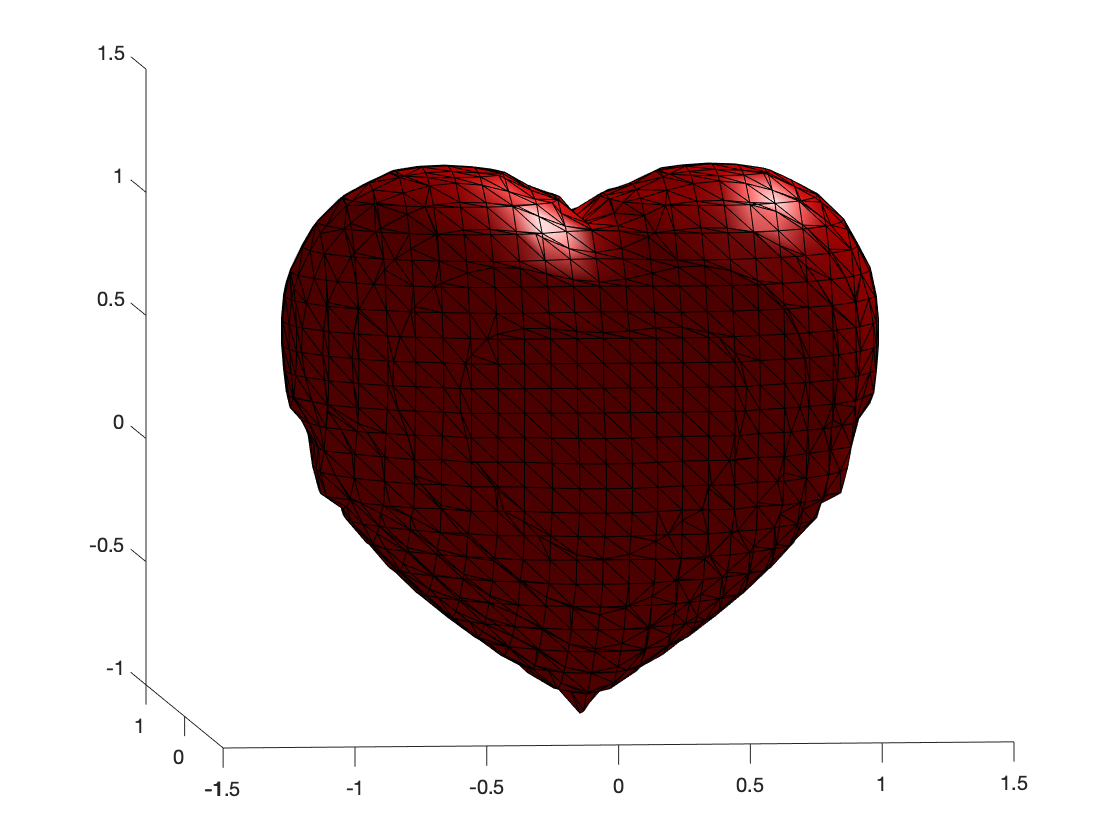

x=-3:0.1:3;
y=-3:0.1:3;
z=-3:0.1:3;
[X,Y,Z]=ndgrid(x,y,z);
F=(-1.*X.^2.*Z.^3)-((9.*Y.^2.*Z.^3)./80)+(X.^2+((9.*Y.^2)./4)+Z.^2-1).^3;
p=patch(isosurface(X,Y,Z,F,0));
p.FaceColor='red';
camlight
lighting gouraud;
view([-5.57 5.89]);